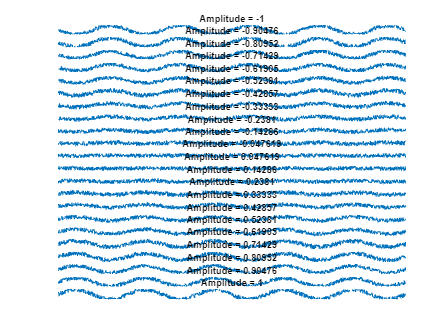

noise = 10;
% Number of channels
numChannels = 22;
% Time vector
t = linspace(0, 1, 1000);
% Generate sinusoidal signals with the same frequency and varying amplitudes
frequency = 5;  % Choose a common frequency for all channels
% Amplitudes ranging from -1 to 1 in 22 divisions
amplitudes = linspace(-1, 1, numChannels);
% Generate sinusoidal signals for each channel
signals = zeros(numChannels, length(t));
for i = 1:numChannels
    signals(i, :) = 10*amplitudes(i) * sin(2 * pi * frequency * t) + noise .* (rand(size(t))-0.5);
end



% Plot the signals in subplots without x and y axes
figure;

for i = 1:numChannels
    subplot(numChannels, 1, i);
    plot(t, signals(i, :));
    title(['Amplitude = ' num2str(amplitudes(i))]);
    ylim([-10 10])
    axis off;  % Hide x and y axes
end

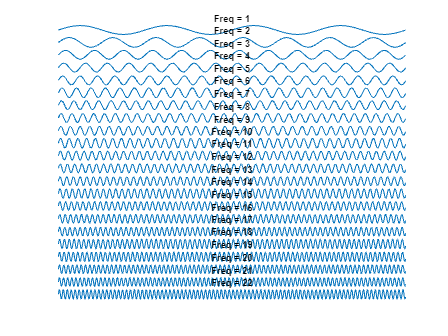

%% Tester
% Define parameters
numFrequencies = 22;
numSamples = 30000;
samplingFrequency = 250;
time = (0:numSamples-1) / samplingFrequency;

% Initialize the array
signalArray = zeros(numFrequencies, numSamples);

% Generate sinusoidal signals and fill the array
for freq = 1:numFrequencies
    frequency = freq; % Hz, you can modify this as needed
    amplitude = 10; % You can adjust the amplitude if needed
    phase = 0; % Phase offset in radians, modify as needed
    
    % Generate sinusoidal signal
    sinusoidalSignal = amplitude * sin(2 * pi * frequency * time + phase);
    
    % Store the signal in the array
    signalArray(freq, :) = sinusoidalSignal;
end

signals = signalArray;

% Plot the signals in subplots without x and y axes
figure;

for i = 1:numChannels
    subplot(numChannels, 1, i);
    plot(t, signalArray(i, :));
    title(['Freq = ' num2str(i)]);
    ylim([-10 10])
    axis off;  % Hide x and y axes
end

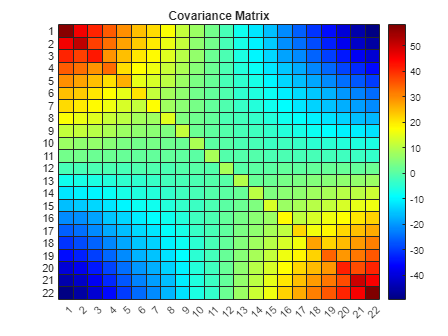

% Calculate covariance matrix
covarianceMatrix = cov(signals');
% Plot covariance matrix as heatmap
figure;
heatmap(covarianceMatrix);
title('Covariance Matrix');
colormap(jet);

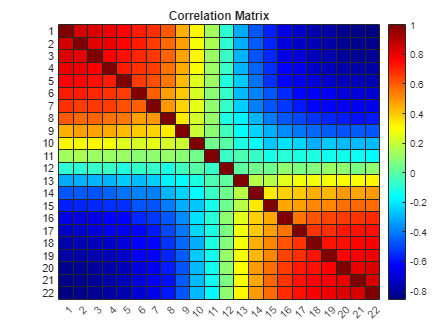

% Calculate correlation matrix
correlationMatrix = corrcoef(signals');
% Plot correlation matrix as heatmap
figure;
heatmap(correlationMatrix);
title('Correlation Matrix');
colormap(jet);

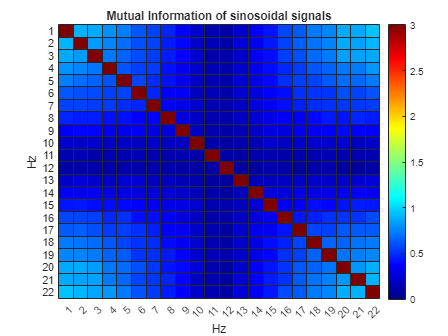

MIM = nan(22,22);

d1 = 0;
for idx_1 = 1:22
    d1 = 1+d1;
    d2 = 0;
    for idx_2 = 1:22
        d2 = 1+d2;
        MIM(idx_1,idx_2) = mutual_information(squeeze(signals(d1,:)'),squeeze(signals(d2,:)')                ,'freedmanDiaconisRule', true);   
    end
end

figure()
h = heatmap(MIM, ...
'XLabel', 'Hz', 'YLabel', 'Hz', ...
'Title', 'Mutual Information of sinosoidal signals');
    % Set the colormap to 'jet'
colormap(jet);

% Customize the axis labels
h.XDisplayLabels = string(1:22);
h.YDisplayLabels = string(1:22);
h.ColorLimits = [0 3];